## [Classification with Machine Learning](https://apmonitor.com/pds/index.php/Main/ClassificationOverview)

Classification is the problem of identifying which set of categories based on observation features. The decision is based on a training set of data containing observations where category membership is known (supervised learning) or where category membership is unknown (unsupervised learning).

A basic example is to determine the number from pixelated images in a built-in sklearn dataset. The script predicts 0-9 from the following images with a Support Vector Classifier.

Dataset: [Data Sets for Deep Learning - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html)

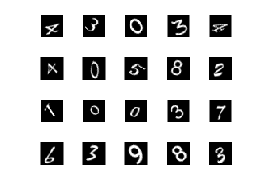

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files)

n_samples = 10000

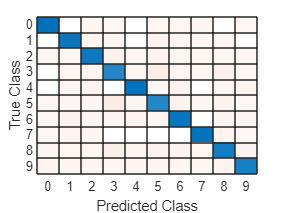


% Extract the images into a matrix
X_data = [];
for i = 1:n_samples
    X_data = [X_data; reshape(readimage(imds,i)',[1,28*28])];
end

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);


% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = fitcecoc(array2table(im2double(X_Train)),Y_Train);
ypred = predict(classifier,array2table(im2double(X_Test)));

% Create a confusion matrix
figure;
confusionchart(Y_Test,ypred)

The confusion matrix shows the number of digits that are correctly classified and how the digits that are misclassified.

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)]

tbl = 5000×785 table
    Var1    Var2    Var3    Var4    Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36    Var37    Var38

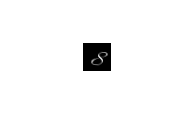


% Select random nummber image
n = randi([0,n_samples],1);
figure;
imshow(imds.Files{n})

reshape(readimage(imds,n)',[1,28*28]);

% Predict number based on image
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Predicted:',yp])

     Predicted:      5 



The following are examples of different classification methods and how they compare to each other

[Classification - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/stats/classification.html)

**Support Vector**

% Fit model
lr = fitcecoc(tbl,"Y_Train",'Learners','svm');

% Predict values
lf_y = predict(lr,im2double(X_Test));
yp = predict(lr,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Support Vector Classifier Predicted:',yp])

     Support Vector Classifier Predicted:      5 




% Calculate the Accuracy
C = confusionmat(lf_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.91



% Duration to fit
f = @() fitcecoc(tbl,"Y_Train",'Learners','svm');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

Time to Evaluate (sec): 2.88


**KNN**

% Fit model
knn = fitcecoc(tbl,'Y_Train',Learners='knn');

% Predict Values
knn_y = predict(knn,im2double(X_Test));
yp = predict(knn,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['K-Nearest Neighbros Predicted:',yp])

     K-Nearest Neighbros Predicted:      8 




% Calculate the Accuracy
C = confusionmat(knn_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 1.00



% Duration to fit
f = @() fitcecoc(tbl,'Y_Train',Learners='knn');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

Time to Evaluate (sec): 0.72


**Tree**

% Fit model
tree = fitcecoc(tbl,'Y_Train',Learners='tree');

% Predict Values
tree_y = predict(tree,im2double(X_Test));
yp = predict(tree,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Decision Tree Predicted:',yp])

     Decision Tree Predicted:      4 




% Calculate the Accuracy
C = confusionmat(tree_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.86



% Duration to fit
f = @() fitcecoc(tbl,'Y_Train',Learners='tree');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

Time to Evaluate (sec): 3.04


**Discriminant**

% Fit model
dis = fitcecoc(tbl,'Y_Train',Learners='discriminant');

% Predict Values
dis_y = predict(dis,im2double(X_Test));
yp = predict(dis,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Distcriminant Predicted:',yp])

     Distcriminant Predicted:      2 




% Calculate Accuracy
C = confusionmat(dis_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.71



% Duration to fit
f = @() fitcecoc(tbl,'Y_Train',Learners='discriminant');
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

Time to Evaluate (sec): 8.46


**Neural Network**

% Fit model
net = fitcnet(tbl,"Y_Train");

% Predict Values
net_y = predict(net,im2double(X_Test));
yp = predict(net,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Neural Network Predicted:',yp])

     Neural Network Predicted:      5 




% Calculate Accuracy
C = confusionmat(net_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.71



%Duration to fit
f = @() fitcnet(tbl,"Y_Train");
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

Time to Evaluate (sec): 11.24


**Random Forest**

% Fit model
% Change NumTrees to view different accuracies
NumTrees = 40;
tbag = TreeBagger(NumTrees,tbl,'Y_Train');

% Predict Values
tbag_y = categorical(predict(tbag,im2double(X_Test)));
yp = predict(tbag,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Random Forest Predicted:',categorical(yp)])

     Random Forest Predicted:      8 




% Calculate Accuracy
C = confusionmat(tbag_y,Y_Test);
accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.99



% Duration to fit
f = @() TreeBagger(NumTrees,tbl,"Y_Train");
time = timeit(f);
fprintf('Time to Evaluate (sec): %.2f\n',time)

Time to Evaluate (sec): 2.05


In this case, the 28x28 (784) pixels are the input features to the classifier. The output of the classifier is a number from 0 to 9. The classifier is trained on 5000 images and tested on the other 50% of the data. This is an example of supervised learning where the data is labeled with the correct number. An unsupervised learning method would not have the number labels on the training set. An unsupervised learning method creates categories instead of using labels.

The first step in classification is to curate the data. This typically involves enumeratation, scaling, outlier detection, and splitting the data into training, test, and an optional validation set. One way to learn about classification methods is through concrete examples where the results are visualized as 2D data. The homogeneous data needs data labels (True/False) because there is no segregation of the data that is required for unsupervised learning methods.